La simulación de los observadores muestran muy buena convergencia y robustez, una vez que el error llegó asintóticamente a cero se mantienen en ese entorno sin diverger.

## Resultados del observador de posición

En la figura XX se muestra el resultado de la convergencia del error del observador de posición.

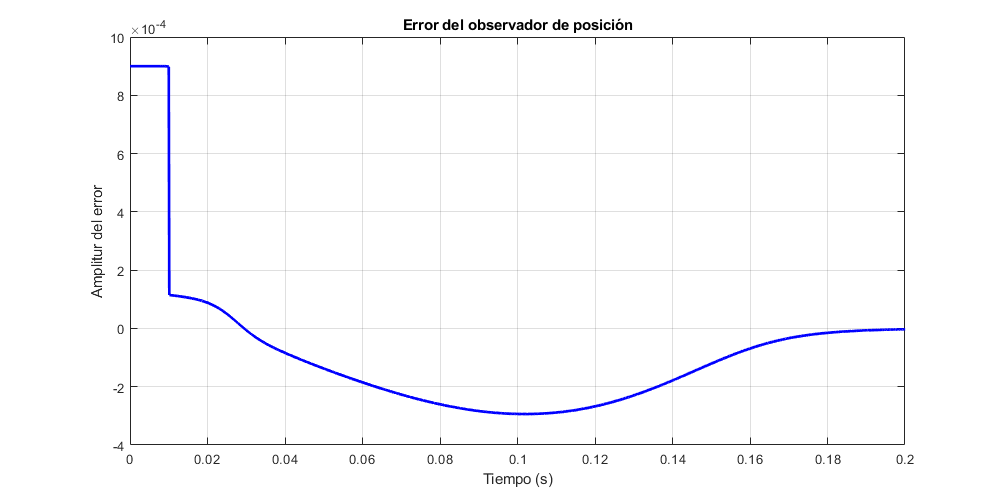

figure('Position', [0, 0, 1000, 500]); 
plot(out_observers.Angles.time, out_observers.Angles.signals(2).values,'b',...
   'LineWidth', 2); 
xlim([0,0.2])
xlabel('Tiempo (s)'); 
ylabel('Amplitur del error'); 
title("Error del observador de posición"); 
grid on;

Como se ve en la figura XX, el ángulo estimado se acerca asintóticamente al ángulo real de posición del rotor y en 5 gíros de mismo el error menor a 0.5 rad.

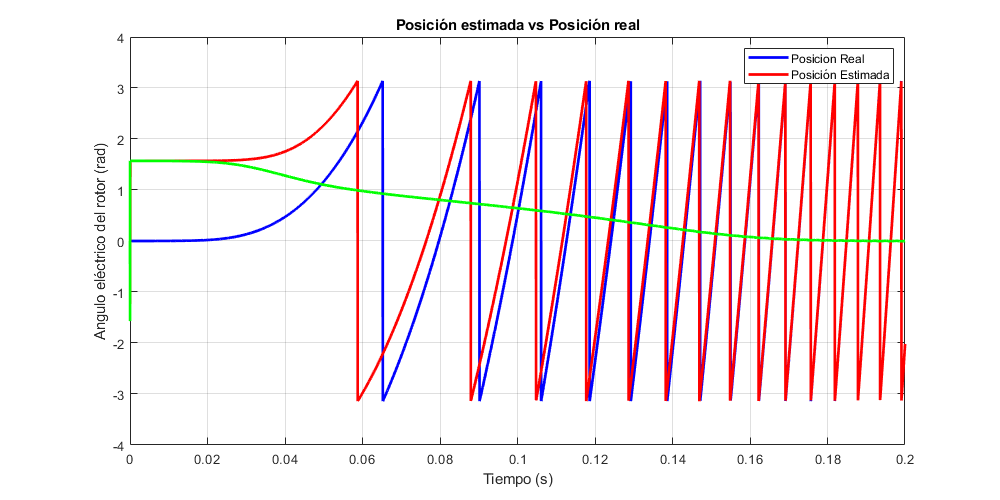

figure('Position', [0, 0, 1000, 500]); 
plot(out_observers.Angles2.time, out_observers.Angles2.signals(1).values(:,1),'b',...
   'LineWidth', 2); 
hold on
plot(out_observers.Angles2.time, out_observers.Angles2.signals(1).values(:,2),'r',...
   'LineWidth', 2); 
hold on
plot(out_observers.Angles2.time, out_observers.Angles2.signals(2).values,'g',...
   'LineWidth', 2);
hold off
xlim([0,0.2])
xlabel('Tiempo (s)'); 
ylabel('Angulo eléctrico del rotor (rad)'); 
title("Posición estimada vs Posición real"); 
legend('Posicion Real', 'Posición Estimada');
grid on;

Las señales senoidales reconstruidas a partir de la estimación del ángulo siguen una dinámica similar a este, y se mantienen estables sin perturbaciones

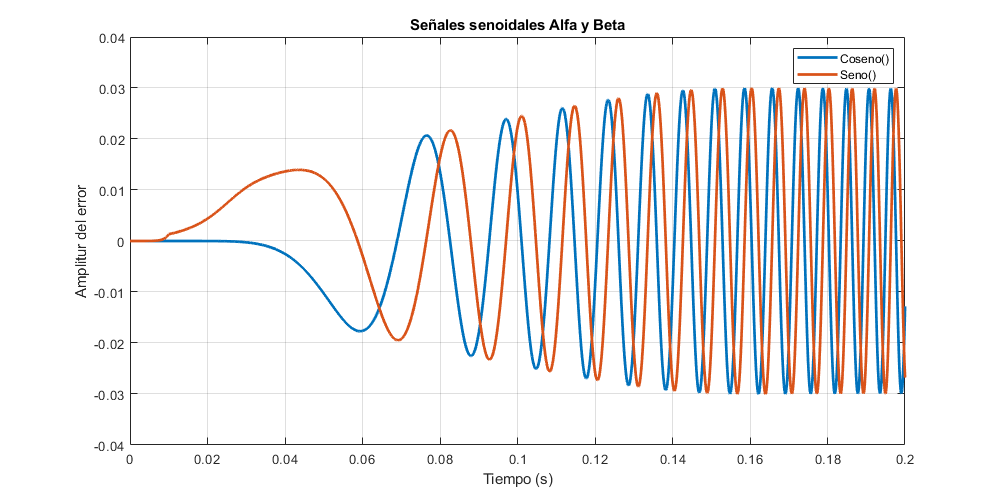

figure('Position', [0, 0, 1000, 500]); 
plot(out_observers.Angles.time, out_observers.Angles.signals(1).values,...
   'LineWidth', 2); 
xlim([0,0.2])
xlabel('Tiempo (s)'); 
ylabel('Amplitur del error'); 
legend('Coseno()', 'Seno()');
title("Señales senoidales Alfa y Beta"); 
grid on;

## Observador del Flujo magnético

El estimador de flujo magnético muestra una convergencia asintótica sin oscilaciones. Como se mencionó anteriormente, la salida del estimador de flujo se usa para el estimador de posición, por lo que su convergencia y robustez son muy importantes para la performance global

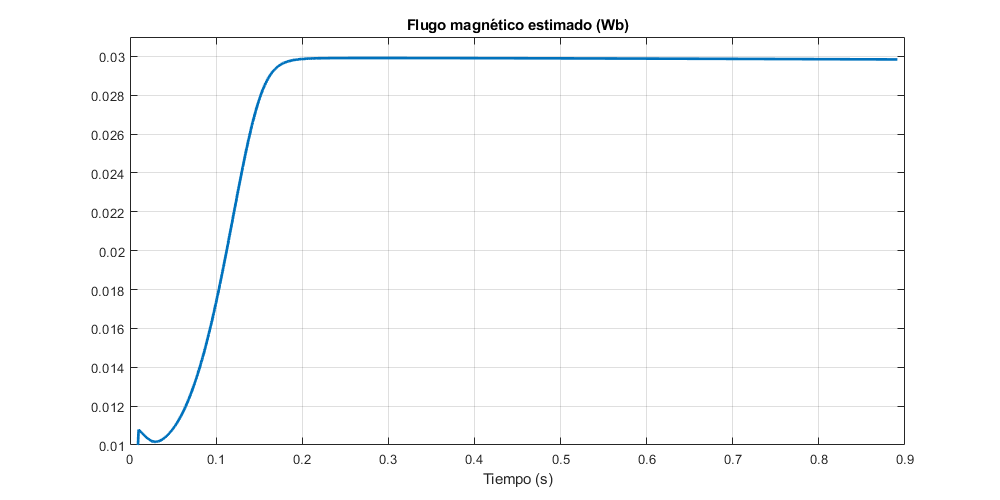

figure('Position', [0, 0, 1000, 500]); 
plot(out_observers.Flux.time, out_observers.Flux.signals.values,...
   'LineWidth', 2); 
ylim([0.01 0.031])
xlabel('Tiempo (s)'); 
ylabel(''); 
title("Flugo magnético estimado (Wb)"); 
grid on;

## Observador de velocidad

En la siguiente imagen se muestra como es el comportamiento del observador de la velocidad de giro de motor

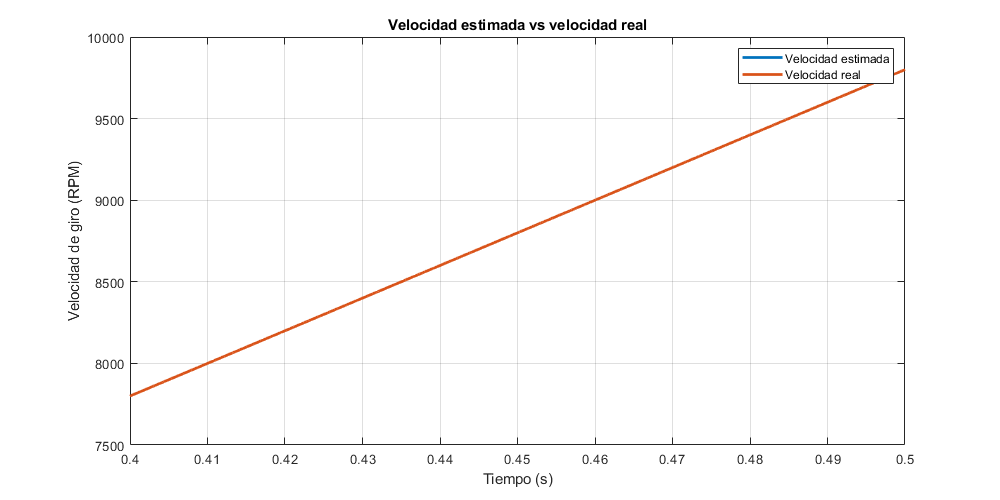

figure('Position', [0, 0, 1000, 500]); 
plot(out_observers.Speed.time, out_observers.Speed.signals(1).values,...
   'LineWidth', 2); 
hold on
plot(out_observers.Speed.time, out_observers.Speed.signals(1).values,...
   'LineWidth', 2); 
hold off
xlim([0.4 0.5])
%ylim([0.4 0.5])
xlabel('Tiempo (s)'); 
ylabel('Velocidad de giro (RPM)'); 
legend('Velocidad estimada', 'Velocidad real');
title("Velocidad estimada vs velocidad real"); 
grid on;